# Feature Analysis

data = readtable("train_desc.csv");

## Preprocess

Convert categories to numerical

data.shape_red = grp2idx(data.shape_red);
data.shape_white = grp2idx(data.shape_white);
data.shape_blue = grp2idx(data.shape_blue);

## NDA

X = data(:,1:(end-1));
X = table2array(X);
Y = data.Sign';
mdl = fscnca(X,Y);

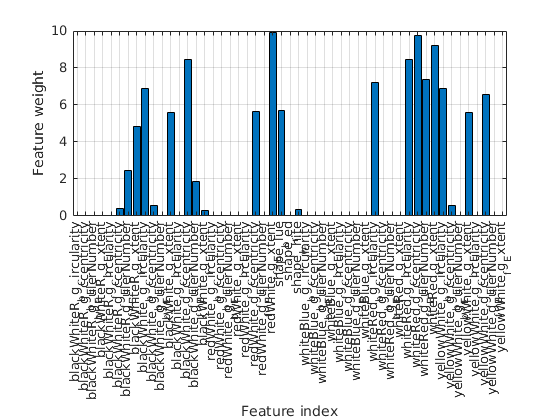

varNames = string(data.Properties.VariableNames(1:(end-1)));
labels = categorical(varNames);
bar(labels, mdl.FeatureWeights)

grid on
xlabel('Feature index')
ylabel('Feature weight')